%close all;
%clear all;
settingsObj = settings;
settingsObj.matlab.editor.AllowFigureAnimation.TemporaryValue = 1;

N = 100;
X = 10*linspace(0,1,N)';
X = [X];       
y = 1 + X + X.*X + 0.2*randn(N,1);  
y = sin(X);


% Train

Omega = [1];  % between components of output vector
sigma = 0.2;
l = 2;


gp = MatrixVariateGaussianProcess(Omega,sigma,l);
gp.set_XY(X,y);
x_new = [6.5];
[mean, cov] = gp.predict(x_new)

mean = 0.1358

cov = 0.1037

% log likelihood
gp.resample(N);
gp.log_likelihood()

ans = 9.3053

[ll, ss, oo] = gp.likelihood_gradients()

ll = 136.6213

ss = -842.0345

oo = -54.0906

gp.fit(100)

*************** WARN:   L < 0 **********************
Iteration: 1, mode: 3, Likelihood for this dataset: 0.001000, der: 50.000000, -50.000000, -40.000000 
*************** WARN:   L < 0 **********************
*************** WARN:   L < 0 **********************
Iteration: 2, mode: 1, Likelihood for this dataset: 0.001000, der: 30.894493, -50.000000, 25.806777 
*************** WARN:   L < 0 **********************
*************** WARN:   L < 0 **********************
Iteration: 3, mode: 1, Likelihood for this dataset: 0.001000, der: 10.231524, -17.975394, 39.637754 
*************** WARN:   L < 0 **********************
*************** WARN:   L < 0 **********************
Iteration: 4, mode: 2, Likelihood for this dataset: 0.001000, der: 13.885269, -24.828110, 40.000000 
*************** WARN:   L < 0 **********************
*************** WARN:   L < 0 **********************
Iteration: 5, mode: 2, Likelihood for this dataset: 0.001000, der: 20.730525, -37.185909, 40.000000 
*************** W

gp.omega

ans = 0.2018

gp.sigma

ans = 1.7209

gp.l

ans = 1.7723

gp.log_likelihood()

*************** WARN:   L < 0 **********************


ans = 1.0000e-03

gp.omega

ans = 0.2005

gp.sigma

ans = 1.6683

gp.l

ans = 1.7366


for i=1:1:N
    [mean, cov] = gp.predict(X(i,:));
    y_train(i,:) = [mean, mean+factor*cov, mean-factor*cov];
end

Omega = [1];  % between components of output vector
sigma = 0.2;
l = 2;%0.3;
% Original
gp_org = MatrixVariateGaussianProcess(Omega,sigma,l);
gp_org.set_XY(X,y);
gp_org.resample(N);
[ll, ss, oo] = gp_org.likelihood_gradients()

ll = 273.5932

ss = -996.9087

oo = -515.9605


x_new = [6.5];
[mean, cov] = gp_org.predict(x_new)

mean = -0.0023

cov = 0.1025

gp_org.omega

ans = 1

gp_org.sigma

ans = 0.3000

gp_org.l

ans = 4

gp_org.resample(N);
gp_org.log_likelihood()

ans = 469.9357

% Original 2
Omega = [1];  % between components of output vector
sigma = 0.2;
l = 2.0;
% Original
gp_org = MatrixVariateGaussianProcess(Omega,sigma,l);
gp_org.set_XY(X,y);
gp_org.resample(N);
[ll, ss, oo] = gp_org.likelihood_gradients()

ll = 136.6213

ss = -842.0345

oo = -54.0906


x_new = [6.5];
[mean, cov] = gp_org.predict(x_new)

mean = 0.1358

cov = 0.1037

gp_org.log_likelihood()

ans = 9.3053

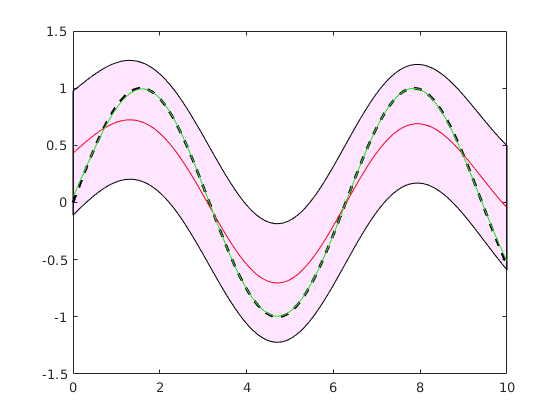

figure(1)
hold off

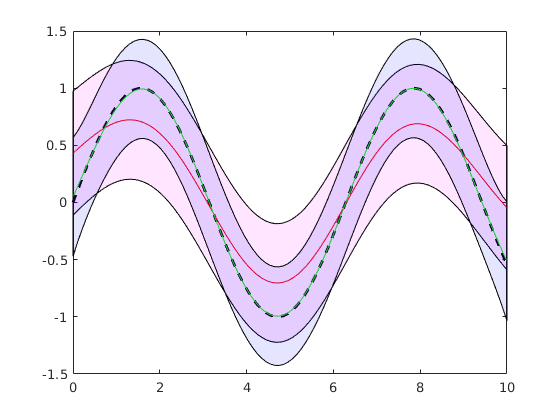

plot(X,y,'k--','LineWidth',2)
hold on
y_org = zeros(N,3);
y_train = zeros(N,3);
factor_org = 5;
factor_train = 20;
for i=1:1:N
    [mean, cov] = gp_org.predict(X(i,:));
    y_org(i,:) = [mean, mean+factor_org*cov, mean-factor_org*cov];
    [mean, cov] = gp.predict(X(i,:));
    y_train(i,:) = [mean, mean+factor_train*cov, mean-factor_train*cov];
end

plot(X,y_org(:,1),'r')
plot(X,y_train(:,1),'g')

patch([X;flipud(X)],[y_org(:,2);flipud(y_org(:,3))],'m','FaceAlpha',0.1); 
patch([X;flipud(X)],[y_train(:,2);flipud(y_train(:,3))],'b','FaceAlpha',0.1); 